%% Synthetic multimodal EEG tensor generator (Live Script)
% Produces Xobs ∈ R^(nChannels x nTime x nTrials) with Tucker-like low-rank
% structure using factors U (spatial), V (temporal), W (trial) and core G.
% Latent ranks requested: R_ch=6, R_time=99, R_trial=17

%% Parameters (change these to suit your needs)
rng(12345);                 % reproducible
nChannels = 32;             % observed sensors (choose as you like)
nTime = 1000;               % observed time samples
nTrials = 60;               % observed trials

% Requested latent ranks
R_ch = 6;                   % spatial subspace dimensionality (your 6D)
R_time = 99;                % temporal subspace dimensionality (your 99D)
R_trial = 17;               % trial subspace dimensionality (your 17D)

sigma = 0.5;                % noise standard deviation (adjust SNR)
use_orthogonal_U = true;    % orthogonalize spatial factors

%% Safety checks & advice
if R_ch > nChannels
    warning('R_ch > nChannels. Consider increasing nChannels or reducing R_ch.');
end
if R_time > nTime
    warning('R_time > nTime. Consider increasing nTime or reducing R_time.');
end
if R_trial > nTrials
    warning('R_trial > nTrials. Consider increasing nTrials or reducing R_trial.');
end


## 1) Generate spatial factors U (nChannels x R_ch)


% Mix of random bases; optionally orthogonalized (QR) like the example in your PDF.
U = randn(nChannels, R_ch);
if use_orthogonal_U
    [Q, ~] = qr(U, 0);
    % If qr returns more columns than R_ch due to rank deficiency, trim/pad:
    Q = Q(:, 1:R_ch);
    U = Q;
end
% Normalize columns
U = bsxfun(@rdivide, U, sqrt(sum(U.^2,1)));


## 2) Generate temporal factors V (nTime x R_time)


% Create a diverse temporal dictionary: sinusoids, chirps, and localized bumps.
t = (0:(nTime-1))' ./ nTime;  % normalized time vector [0,1)
V = zeros(nTime, R_time);

% Fill first block with low-frequency sinusoids
n_sin = min(30, R_time);  % a block of sinusoids
freqs = linspace(1, 40, n_sin);  % Hz-like placeholders (conceptual)
for k = 1:n_sin
    V(:,k) = sin(2*pi*freqs(k)*t*5); % scale so modes are distinct
end

% Next block: transient Gaussian bumps at random centers
n_bumps = min(30, R_time - n_sin);
for k = 1:n_bumps
    center = rand()*0.9 + 0.05;
    width = 0.01 + 0.05*rand();
    V(:, n_sin + k) = exp(-((t - center).^2)/(2*width^2));
end

% Remaining: random smooth components using filtered noise
remaining = R_time - (n_sin + n_bumps);
for k = 1:remaining
    raw = randn(nTime,1);
    % simple smoothing via convolution
    win = gausswin(21);
    win = win / sum(win);
    smooth_comp = conv(raw, win, 'same');
    V(:, n_sin + n_bumps + k) = smooth_comp;
end

% Orthogonalize/time-normalize temporal basis for numerical stability
[Vq, ~] = qr(V, 0);
V = Vq(:, 1:R_time);
V = bsxfun(@rdivide, V, sqrt(sum(V.^2,1)));


## 3) Generate trial factors W (nTrials x R_trial)


% Trial-level variability: block factors, linear trends, and random scalings.
W = zeros(nTrials, R_trial);

% First few components: simple trial scaling shapes (e.g., gradual trend)
n_trend = min(5, R_trial);
for k = 1:n_trend
    W(:,k) = linspace(0.5, 1.5, nTrials)' .* (0.9 + 0.2*randn);
end

% Next: categorical-like factors (blocks)
n_blocks = min(6, R_trial - n_trend);
block_size = max(1, floor(nTrials / (n_blocks+1)));
for k = 1:n_blocks
    idx = (1 + (k-1)*block_size) : min(nTrials, k*block_size);
    vec = zeros(nTrials,1);
    vec(idx) = 1;
    W(:, n_trend + k) = vec .* (0.5 + rand());
end

% Remaining: gaussian noise components
remaining_t = R_trial - (n_trend + n_blocks);
for k = 1:remaining_t
    W(:, n_trend + n_blocks + k) = randn(nTrials,1);
end

% Orthogonalize and normalize trial factors
[Wq, ~] = qr(W, 0);
W = Wq(:, 1:R_trial);
W = bsxfun(@rdivide, W, sqrt(sum(W.^2,1)));


## 4) Core tensor G (R_ch x R_time x R_trial)


% Choose a small dense core that defines interactions. Options:
%   - all ones (simple equal-weight interactions)
%   - diagonal-like (couple first K components)
%   - random low-magnitude
% We'll create a core with moderate structure: mostly diagonal-block + small random.
G = zeros(R_ch, R_time, R_trial);

% fill with small random amplitude and a banded strong diagonal-ish structure
for r = 1:R_ch
    for s = 1:R_time
        % Map s into a coarse bin that aligns roughly with r (toy structural coupling)
        if mod(s, R_ch) == mod(r, R_ch)
            % slightly stronger coupling
            G(r,s, :) = 1.0 * (0.8 + 0.4*randn(1,1));
        else
            G(r,s, :) = 0.05 * randn(1, R_trial);
        end
    end
end
% small smoothing to avoid extremely large values
G = G / max(abs(G(:))) * 1.0;


## 5) Assemble the clean tensor Xclean = G ×1 U ×2 V ×3 W


% We'll use mode-n products. Implement a helper inline function for mode-n product.
mode_n_product = @(X, A, n) tensor_mode_product(X, A, n); % helper below

Xclean = G;
Xclean = mode_n_product(Xclean, U, 1);   % mode-1 product (spatial)
Xclean = mode_n_product(Xclean, V, 2);   % mode-2 product (temporal)
Xclean = mode_n_product(Xclean, W, 3);   % mode-3 product (trial)

% Xclean now is sized (nChannels x nTime x nTrials)


## 6) Add Gaussian noise -> observed tensor Xobs


E = sigma * randn(size(Xclean));
Xobs = Xclean + E;


## 7) Quick sanity visualizations (slice, example channels, trial averages)

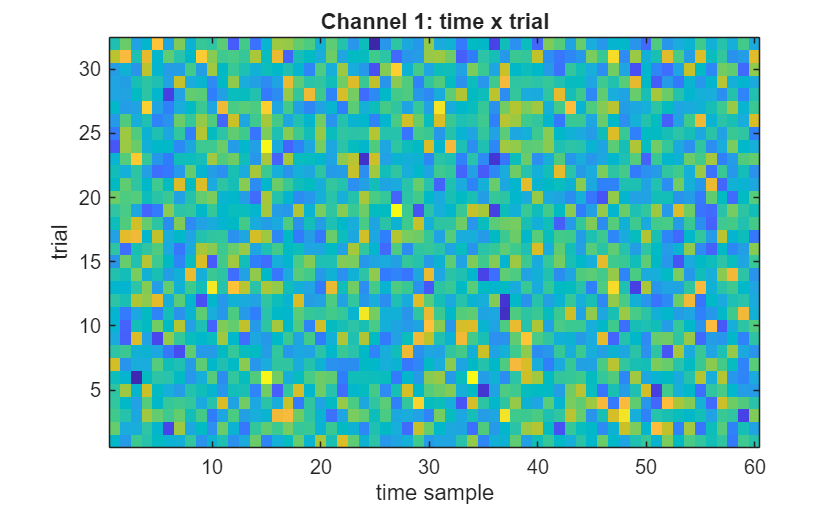



% Example: show a single-channel time x trials image (channel 1)
figure('Name','Channel 1 time x trial map');
imagesc(squeeze(Xobs(1,:,:))'); axis xy;
xlabel('time sample'); ylabel('trial'); title('Channel 1: time x trial');

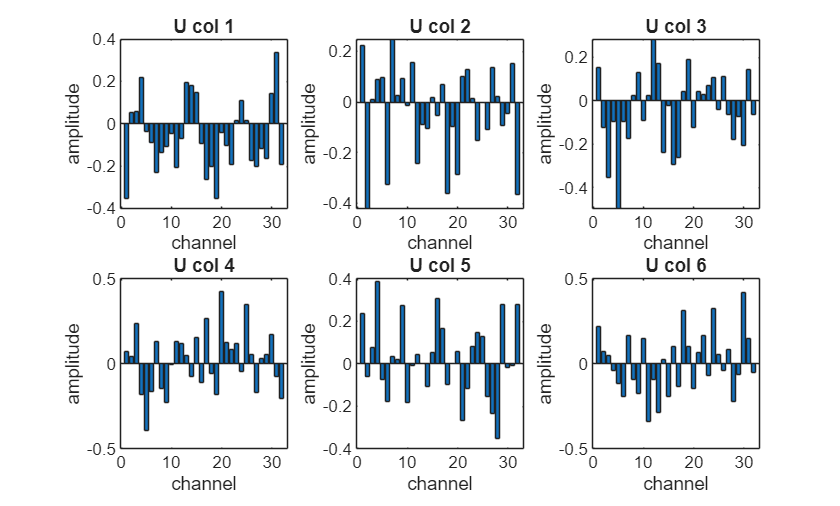


% Example: plot first 6 spatial patterns (U)
figure('Name','Spatial factors (U)');
for k = 1:min(R_ch,6)
    subplot(2,3,k);
    bar(U(:,k));
    title(sprintf('U col %d', k));
    xlabel('channel'); ylabel('amplitude');
end

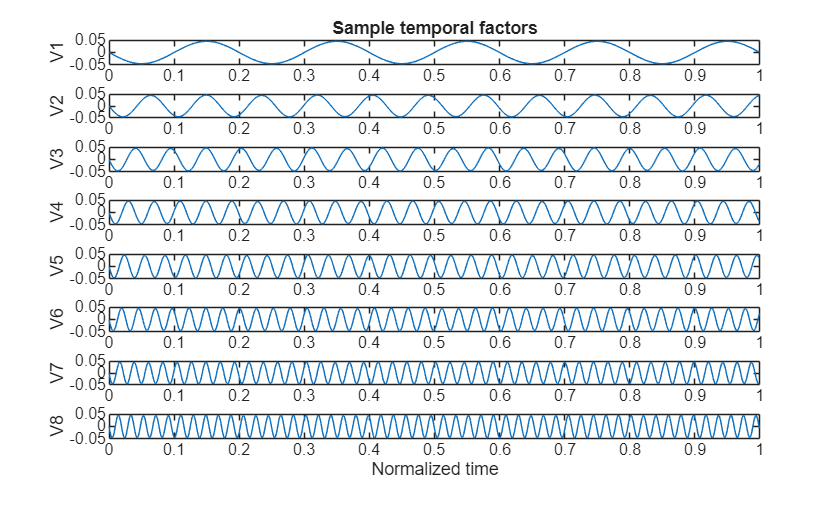


% Example: plot some temporal modes
figure('Name','Temporal modes (first 8)');
nplot = min(8, R_time);
for k = 1:nplot
    subplot(nplot,1,k);
    plot(t, V(:,k));
    ylabel(sprintf('V%d',k));
    if k==1; title('Sample temporal factors'); end
end
xlabel('Normalized time');

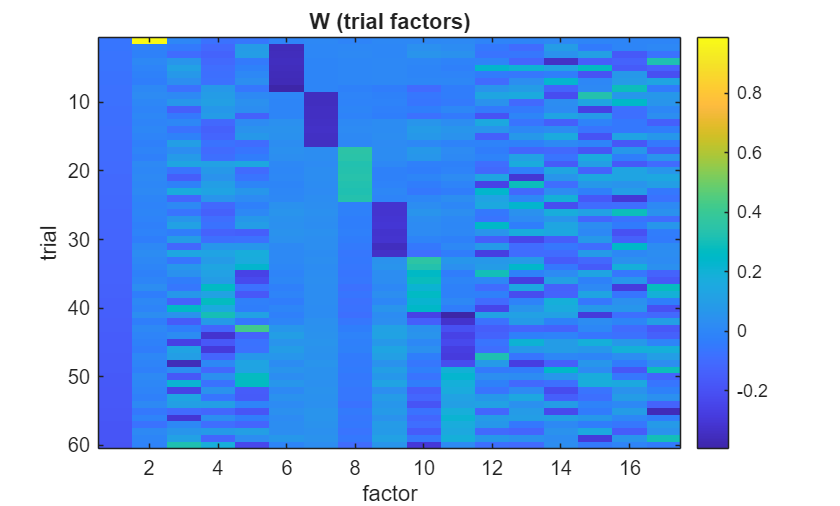


% Example: trial factor heatmap
figure('Name','Trial factors W (heatmap)');
imagesc(W); xlabel('factor'); ylabel('trial'); title('W (trial factors)');
colorbar;

## 8) Save outputs (optional)


% save synthetic_EEG_tensor.mat Xobs Xclean U V W G -v7.3
% 

## Helper function: mode-n product for a dense core tensor

function Y = tensor_mode_product(X, A, mode)
% X: tensor array of size (I1 x I2 x I3) implemented as a numeric array
% A: matrix of size (J x In) where In is size(X,mode)
% mode: 1, 2, or 3
% Result Y has dimension where mode dimension replaced by J.
    sz = size(X);
    if numel(sz) < 3, sz(3) = 1; end
    switch mode
        case 1
            % reshape to (In x (I2*I3))
            Xmat = reshape(X, sz(1), []);
            Ymat = A * Xmat;                    % (J x ...)
            newSz = [size(A,1), sz(2), sz(3)];
            Y = reshape(Ymat, newSz);
        case 2
            % permute so mode-2 is first
            Xperm = permute(X, [2 1 3]);       % (I2 x I1 x I3)
            Xmat = reshape(Xperm, sz(2), []);
            Ymat = A * Xmat;                    % (J x ...)
            newSz = [size(A,1), sz(1), sz(3)];  % (J x I1 x I3)
            Yperm = reshape(Ymat, newSz);
            Y = ipermute(Yperm, [2 1 3]);
        case 3
            Xperm = permute(X, [3 1 2]);       % (I3 x I1 x I2)
            Xmat = reshape(Xperm, sz(3), []);
            Ymat = A * Xmat;
            newSz = [size(A,1), sz(1), sz(2)];
            Yperm = reshape(Ymat, newSz);
            Y = ipermute(Yperm, [2 3 1]);
        otherwise
            error('Mode must be 1, 2 or 3');
    end
end
